# Problem 20.20

clear
constants

===== Start of script constants.m =====


NA = 6.0200e+23

R = 8.3100

k = 1.3804e-23

torr2pa = 133.3200

cal2J = 4.1840

atm2Pa = 101300

C0K = 273.1500

===== End of script constants.m =====


n = 1;    % 1 mole of monatomic gas, Cv = 3/2*R
p1 = 5e3; T1 = 600; V1 = 1;
V2 = 2; a = 1;

p-V function definition

syms V real positive
p = 5e3*exp((V1-V)/a)

$$p = 5000\,{\mathrm{e}}^{1-V}$$

(a) Final pressure

p2 = double(subs(p,V,V2))

p2 = 1.8394e+03

(b) Final temperature. $pV=nRT$

T2 = p2*V2/(n*R)

T2 = 442.6949

(c) Work done by the gas during the expansion: $dW = p dV$ thus $W = \int_{V_1}^{V_2}{p dV}$

W = double(int(p,V,V1,V2))

W = 3.1606e+03

(d) $\Delta S$ for the expansion

Cv = 3/2*R

Cv = 12.4650

dS = n*R*log(V2/V1)+n*Cv*log(T2/T1)

dS = 1.9701

p-V plot

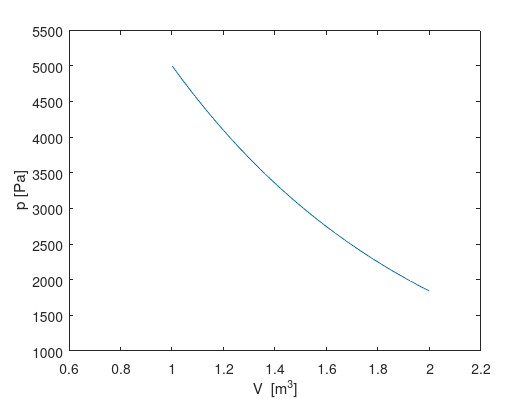

fplot(p,[V1 V2]), axis([V1*0.6 V2*1.1 1000 5500])
xlabel('V [m^3]'), ylabel('p [Pa]')